d = './CarData/TrainImages';
files = dir(d);
X = [];
Y = [];

for f = files'
    if ~f.isdir
        im = imread([d, '/', f.name]);
        
        % Compute grayscale histogram with 256 bins
        histogram = histcounts(im(:), linspace(0, 255, 257));
        
        % Feature vector is the histogram
        fv = histogram;
        
        X(end+1, :) = fv;
        
        % Extract class label from file name (neg or pos)
        class_label = f.name(1:3);
        Y(end+1, 1) = ~strcmp(class_label, 'neg');
    end
end

% Set the random number generator's seed for reproducibility
rng(0);

% Shuffle the data and split into training and validation sets
num_samples = size(X, 1);
indices = randperm(num_samples);

training_ratio = 2/3;
num_training = round(training_ratio * num_samples);

train_indices = indices(1:num_training);
validation_indices = indices(num_training+1:end);

X_train = X(train_indices, :);
Y_train = Y(train_indices, :);

X_validation = X(validation_indices, :);
Y_validation = Y(validation_indices, :);

% Classification using k-Nearest Neighbors (k-NN)
k = 5;  % Number of neighbors
num_validation_samples = size(X_validation, 1);
predicted_labels = zeros(num_validation_samples, 1);

for i = 1:num_validation_samples
    % Calculate distances between the validation sample and all training samples
    distances = sqrt(sum((X_train - X_validation(i, :)).^2, 2));
    
    % Get the indices of the k-nearest neighbors
    [~, sorted_indices] = sort(distances);
    k_indices = sorted_indices(1:k);
    
    % Classify the validation sample based on majority class among neighbors
    k_labels = Y_train(k_indices);
    predicted_labels(i) = mode(k_labels);
end

% Calculate accuracy
accuracy = sum(predicted_labels == Y_validation) / num_validation_samples;
fprintf('Validation Accuracy: %.2f%%\n', accuracy * 100);

Validation Accuracy: 52.57%


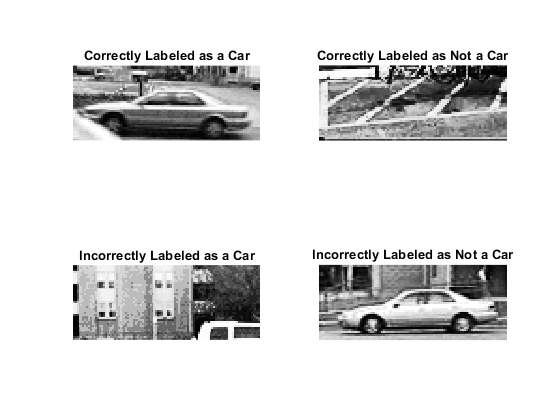



% Find indices of examples for each category
correct_car_idx = find(predicted_labels == 1 & Y_validation == 1, 1);
correct_not_car_idx = find(predicted_labels == 0 & Y_validation == 0, 1);
incorrect_car_idx = find(predicted_labels == 1 & Y_validation == 0, 1);
incorrect_not_car_idx = find(predicted_labels == 0 & Y_validation == 1, 1);

% Display example images
figure;

% Correctly labeled as a car
subplot(2, 2, 1);
imshow(imread(fullfile(d, files(validation_indices(correct_car_idx)).name)));
title('Correctly Labeled as a Car');

% Correctly labeled as not a car
subplot(2, 2, 2);
imshow(imread(fullfile(d, files(validation_indices(correct_not_car_idx)).name)));
title('Correctly Labeled as Not a Car');

% Incorrectly labeled as a car
subplot(2, 2, 3);
imshow(imread(fullfile(d, files(validation_indices(incorrect_car_idx)).name)));
title('Incorrectly Labeled as a Car');

% Incorrectly labeled as not a car
subplot(2, 2, 4);
imshow(imread(fullfile(d, files(validation_indices(incorrect_not_car_idx)).name)));
title('Incorrectly Labeled as Not a Car');